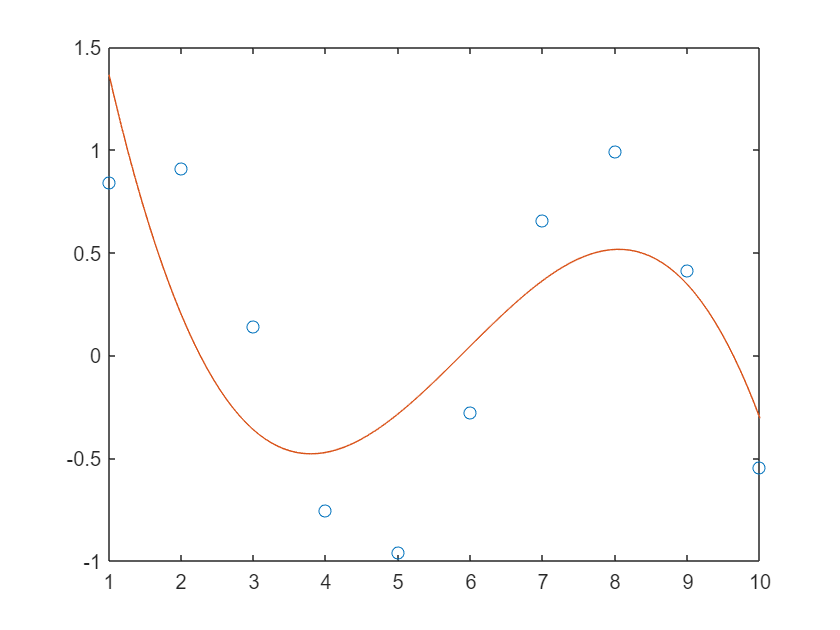

x = 1:10;
y = sin(1:10);

phi = @(x)[ones(1, length(x)); x; x.^2; x.^3];

xAprox = x(1):(x(length(x))-x(1))/100:x(length(x));
yAprox = least_squares_approx(x, y, phi, xAprox);

plot(x, y, 'o', xAprox, yAprox, '-');